# 例1.7（認識処理）

村松正吾　「多次元信号・画像処理の基礎と展開」

動作確認： MATLAB R2017a

以下のツールボックスが必要

- Neural Network Toolbox

予めサポートパッケージ

- Neural Network Toolbox Importer for Caffe Models

を導入すること

参考サイト

- [importCaffeNetwork](https://jp.mathworks.com/help/nnet/ref/importcaffenetwork.html)

- [分類用のシンプルな深層学習ネットワークの作成](https://jp.mathworks.com/help/nnet/examples/create-simple-deep-learning-network-for-classification.html)

## 画像データの読込と抽出

ImageDatastore オブジェクトとして数字サンプルデータを読み込み

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
        'nndatasets','DigitDataset');
digitData = imageDatastore(digitDatasetPath, ...
        'IncludeSubfolders',true,'LabelSource','foldernames');

## データセットから一部の文字画像をランダム抽出

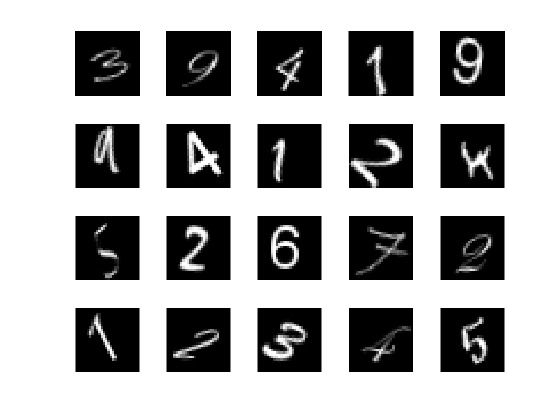

figure
[nRows, nCols] = size(readimage(digitData,1));
nSamples = 20;
testImg = zeros(nRows,nCols,1,nSamples,'uint8');
perm = randperm(10000,20);
for idx = 1:20
    subplot(4,5,idx);
    testImg(:,:,1,idx) = readimage(digitData,perm(idx));
    imshow(testImg(:,:,1,idx));
end
%print('fig01-04a','-dpng')

## 事前学習済みのCNNモデルを Caffe からインポート

% インポートファイルの指定 
protofile = 'digitsnet.prototxt'; 
datafile = 'digits_iter_10000.caffemodel';
% ネットワークのインポート
net = importCaffeNetwork(protofile,datafile);
disp(net.Layers)

  7x1 Layer array with layers:

     1   'testdata'   Image Input             28x28x1 images
     2   'conv1'      Convolution             20 5x5x1 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu1'      ReLU                    ReLU
     4   'pool1'      Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   'ip1'        Fully Connected         10 fully connected layer
     6   'loss'       Softmax                 softmax
     7   'output'     Classification Output   crossentropyex with 'class1', 'class2', and 8 other classes


## 畳込み層(conv1)の重み係数を[0,1]に正規化して表示

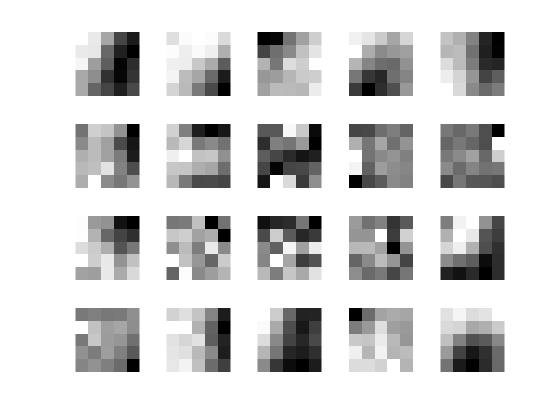

figure
weights = squeeze(net.Layers(2).Weights);
for idx = 1:20
    filter = weights(:,:,idx);
    mx = max(filter(:));
    mn = min(filter(:));
    filter = (filter-mn)/(mx-mn);
    subplot(4,5,idx);
    imshow(filter);
end
%print('fig01-04b','-dpng')

## 数字画像の分類デモ

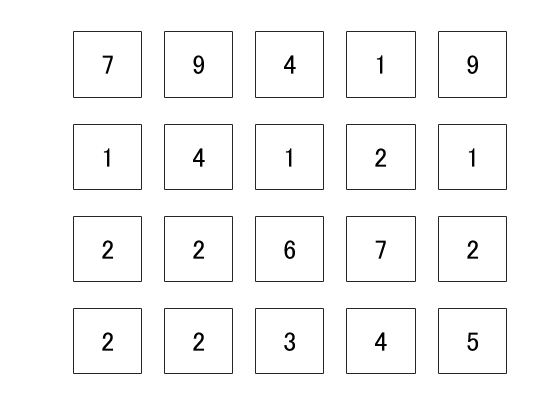

figure
labelList = categories(digitData.Labels);
answers = classify(net,testImg);
classList = categories(answers);
answers = renamecats(answers,classList,labelList);
for idx = 1:20
    subplot(4,5,idx);
    text(0.4,0.5,string(answers(idx)),'FontSize',20)
    ax = gca;
    ax.Box = 'on';
    ax.XTick = [];
    ax.YTick = [];
end
%print('fig01-04c','-dpng')

## 分類精度の計算

refdata = digitData.Labels(perm);
accuracy = sum(refdata == answers)/numel(answers)

accuracy = 0.7500